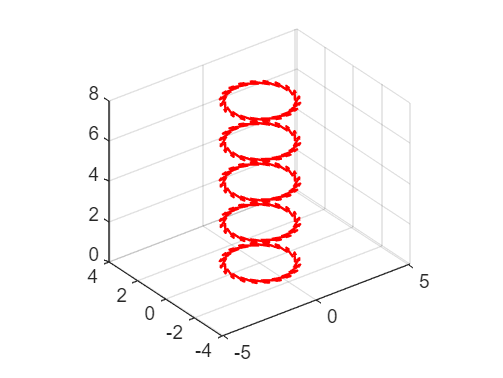

nl = 5;
N = 20;
R = 1.5;
sz = 1;
I = 300;
mo = 4*pi * 1e-7;
km = mo * I / (4*pi);
rw = 0.2;

angulo = linspace(0, 2*pi, N + 1);
angulo(end) = [];

x = R * cos(angulo);
y = R * sin(angulo);

dx = R * -sin(angulo);
dy = R * cos(angulo);
dz = zeros(1, N);
z = zeros(1, N);

figure;
hold on;
axis equal;
view(3);
grid on;

for k = 0:nl - 1
    z_espiral = z + k * ((nl - 1)/2);
    quiver3(x, y, z_espiral, dx, dy, dz, 'r', 'LineWidth',1.2);
end

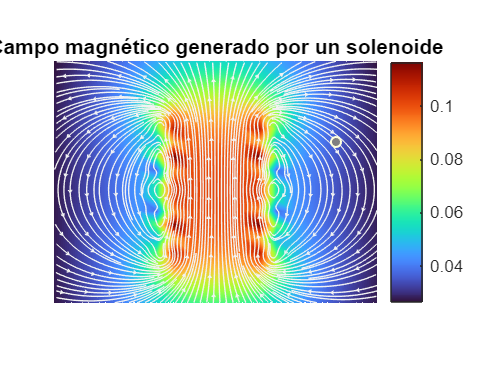


malla_x = linspace(-5, 5, N);
malla_y = linspace(-2, 2, N);
malla_z = linspace(-2, 6, N);

Bx_total = zeros(N, N, N);
By_total = zeros(N, N, N);
Bz_total = zeros(N, N, N);


for i = 1:length(malla_x)
    for j = 1:length(malla_y)
        for k = 1:length(malla_z)
            Bx = 0; By = 0; Bz = 0;

            for n = 0:nl -1
                for l = 1:N
                    x0 = malla_x(i);
                    y0 = malla_y(j);
                    z0 = malla_z(k);

                    x_seg = x(l);
                    y_seg = y(l);
                    z_seg = z(l) + n * sz;

                    r_vec = [x0 - x_seg, y0 - y_seg, z0 - z_seg];
                    r_mag = norm(r_vec);

                    if r_mag == 0
                        continue
                    end

                    
                    dl = [dx(l), dy(l), dz(l)];
                    dB = km * cross(dl, r_vec) / (r_mag^3);

                    Bx = Bx + dB(1);
                    By = By + dB(2);
                    Bz = Bz + dB(3);
                
                end
            end

            Bx_total(i,j,k) = Bx;
            By_total(i,j,k) = By;
            Bz_total(i,j,k) = Bz;
        end
    end
end

%Visualizacion

centery = round(N / 2);

% Extraer componentes del plano XZ
Bx_xz = squeeze(Bx_total(:, centery, :));
Bz_xz = squeeze(Bz_total(:, centery, :));
Bmag_xz = sqrt(Bx_xz.^2 + Bz_xz.^2);

% Malla para graficar
[Xgrid, Zgrid] = meshgrid(malla_x, malla_z);

figure(2)
clf

% Fondo 
pcolor(Xgrid, Zgrid, Bmag_xz'.^(1/3));
shading interp
colormap(turbo)
colorbar

% Líneas de flujo
h1 = streamslice(Xgrid, Zgrid, Bx_xz', Bz_xz', 4);  
set(h1, 'Color', [1 1 1]*0.95);

% Mejoras visuales
axis equal tight
axis off
title('Campo magnético generado por un solenoide');